# Implementação de uma função para resolver uma equação de diferenças

Aluno: Pedro Henrique Garcia

R.A. 1829696

## Inicialização dos vetores

close all; clear; clc; % faça a coleta de lixo regularmente

%tamanho do b
b_size = 100;
%tamanho a
a_size = 50;

`poly` Deveria garantir que o sistema é estável, pois todas raízes serão menores que 1, em magnitude, e portanto estão dentro do circulo unitário para números grandes de a_size, o sistema sistema continuará instável pois `max(abs(roots(a))` pode ser > 1.


a = poly(0.01*rand(a_size,1));
b = randn(b_size, 1); % declara b
x = randn(100,1); % declara o sinal

## Função de resolução de equações de diferenças

% function y = phg_filter(b,a,x)

% a função phg_filter recebe três argumentos, para resolver a equação de
% difereças. 
% a é um vetor dos coeficientes que acompanham y
% b é um vetor dos coeficientes que acompanham x
% x é um vetor do sinal
% Uma equação de diferenças é do tipo:
% a(n)y(n) + a(n-1)y(n-1) ... a(1)y(1) = b(n)x(n) + b(n-1)x(n-1) ... b(1)x(1)
% podemos encontrar a saída conhecendo apenas

% pega o maior numero 
% pra servir de padrão pro produto escalar
% espero que o compilador do matlab seja bom o suficiente para pular todas
% as multiplicações por zeros desnecessárias
max_size = max([numel(x) numel(a) numel(b)]); 

% preenche o restante com zeros, até max_size
y(max_size) = 0;
y = transpose(y);
a(max_size) = 0;
b(max_size) = 0;

% protege contra um vetor coluna, a e b precisam ser linhas
if (isrow(b)==0)
    b = transpose(b);
end
if (isrow(a) == 0)
    a = transpose(a);
end
% assegura que x é vetor coluna
if (iscolumn(x) == 0)
    x = transpose(x);
end

% resolve a equação de diferenças
for n=1:numel(x)
    y(n) = (1/a(1))*( b(1:n)*x(n:-1:1) -a(2:n)*y(n-1:-1:1) );
end

%trunca a saída para que a comparação com a função do matlab possa ser feita
y = y( 1:numel(x) );

## Testes das funções

Testando o tempo de execução das duas funções.

tic; y_matlab=filter(b,a,x); toc

Elapsed time is 0.017484 seconds.


tic; y_phg=phg_filter(b,a,x); toc

Elapsed time is 0.009694 seconds.


Verificando se o sistema é estável

% se max(abs(roots(a))) >1, então sistema instável. 
max(abs(roots(a)))

ans = 0.1391

Podemos ver o maior erro entre a função escrita e o filter do matlab

% mostra o maior erro entre o phg_filter e o filter do matlab
maxerror = max( abs(y_matlab -y_phg) )

maxerror = 1.7764e-14

Plot do erro entre as duas funções

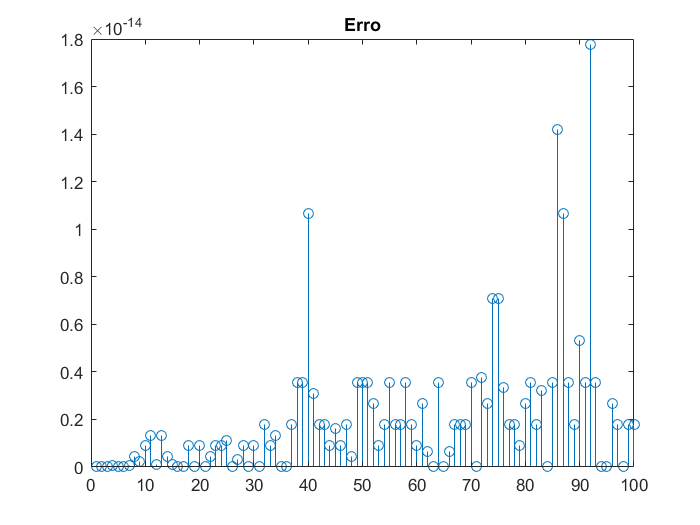

% plota o erro entre o phg_filter e o filter do matlab
figure
stem( abs(y_matlab -y_phg)) 
title('Erro')

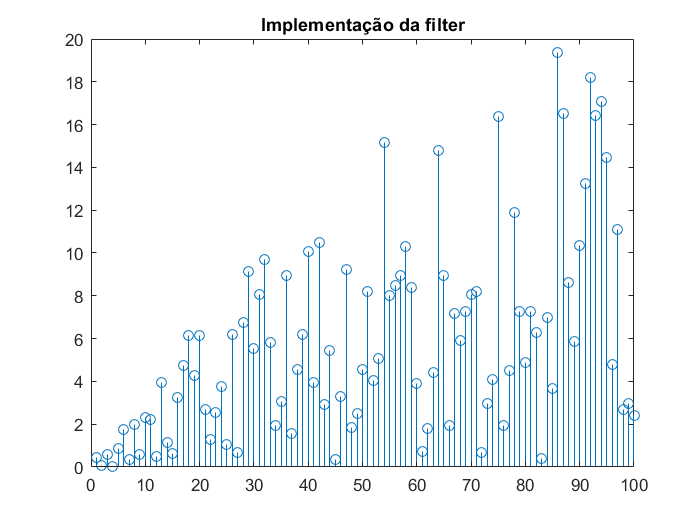


figure
stem(abs(y_phg))
title('Implementação da filter')

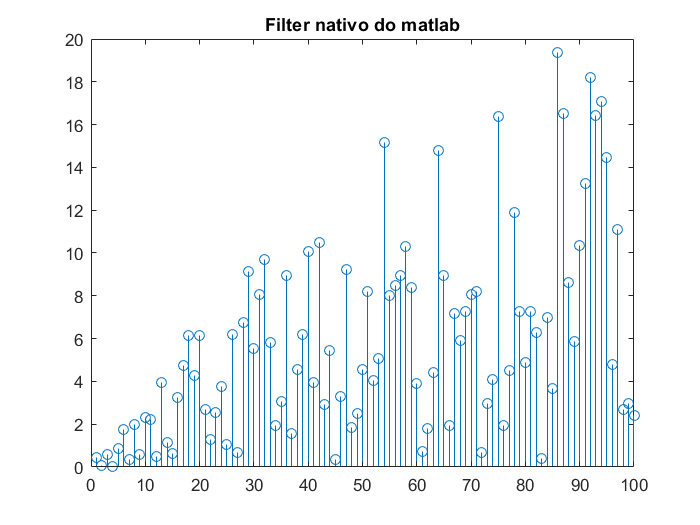

figure
stem(abs(y_matlab))
title('Filter nativo do matlab')